format longg;

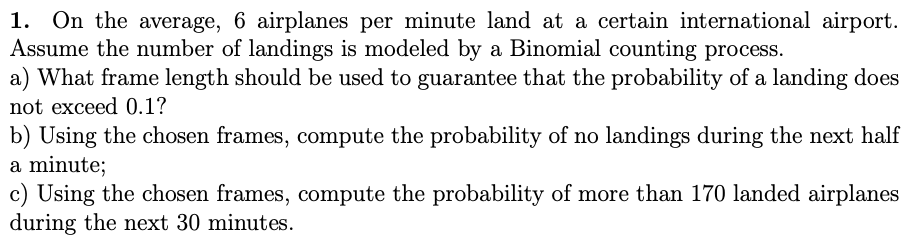

% a) Frame length to guarantee some probability
lambda = 6; % planes per minute
p_max = 0.1;
delta = p_max / lambda; % Frame length in minutes
delta_sec = delta * 60;
fprintf("a) Frame length in seconds: %g", delta_sec);

a) Frame length in seconds: 1

% b) Probability of no landings during the next half a minute
n_b = 30; % number of frames for half a minute
p = 0.1; % probability of landing per frame
prob_no_landings = binopdf(0, n_b, p);
fprintf("b) P(no landings during the next half minute) = %g", prob_no_landings);

b) P(no landings during the next half minute) = 0.0423912

% c) Probability of more than 170 landed airplanes during the next 30 minutes
n_b = 30 * 60; % number of frames for 30 minutes
p = 0.1; % probability of landing per frame
prob_at_most_170 = binocdf(170, n_b, p);
prob_more_than_170 = 1 - prob_at_most_170;
fprintf("c) P(more than 170 landed airplanes during next 30 minutes) = %g", prob_more_than_170);

c) P(more than 170 landed airplanes during next 30 minutes) = 0.770884

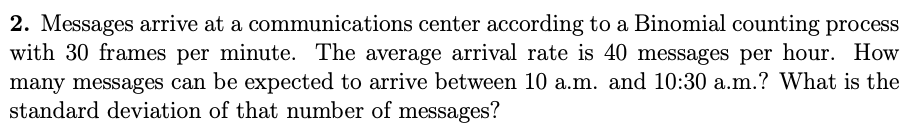

lambda = 40/60; % messages per minute
delta = 1/30; % frame length in minutes
p = lambda * delta % probability of a message arriving at a certain frame

p =         0.0222222222222222


interval = 30; % time frame to check the expected messages
n = interval/delta; % number of frames in the given time frame
expected_messages = interval/delta * p;
fprintf("E(X) = %g", expected_messages);

E(X) = 20

standard_deviation = sqrt(n * p * (1-p));
fprintf("sigma(X) = %g", standard_deviation);

sigma(X) = 4.42217

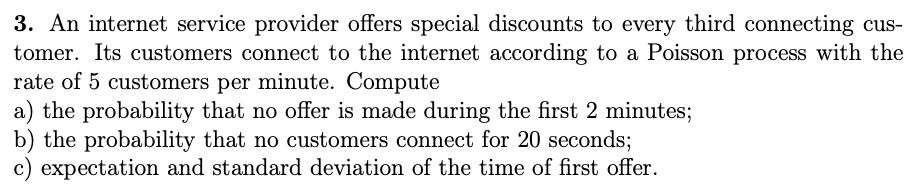

% a) Probability that no offer is made during the first 2 minutes
lambda = 5; % per minute
lambda_t = lambda * 2; % the first two minutes
% P(no offer) = P(X < 3) = P(X <= 2)
p_no_offer = poisscdf(2, lambda_t);
fprintf("a) P(no offer in 2 minutes) = %g", p_no_offer)

a) P(no offer in 2 minutes) = 0.0027694

% b) No customer connects for 20 seconds
lambda_t = lambda * 20/60;
p_no_customer = poisspdf(0, lambda_t);
fprintf("b) P(no customer in 20 seconds) = %g", p_no_customer)

b) P(no customer in 20 seconds) = 0.188876

% c) expectation and standard deviation of the first time of first order
alpha = 3; % we need 3 events to happen in total
expected_first_offer = alpha * 1/lambda;
fprintf("c) E(first offer) = %g", expected_first_offer);

c) E(first offer) = 0.6

std_first_offer = sqrt(alpha * 1/lambda^2);
fprintf("   std(first offer) = %g", std_first_offer)

   std(first offer) = 0.34641

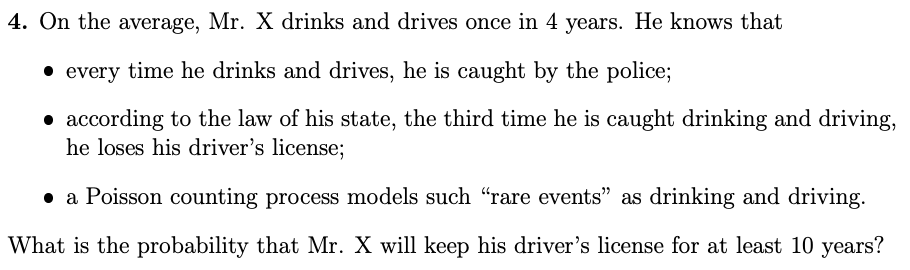

lambda = 1/4; % times a year
lambda_t = lambda * 10; % times 10 years
prob_keeping_license = poisscdf(2, lambda_t);
fprintf("P(Mr. X keeps his license) = %g", prob_keeping_license);

P(Mr. X keeps his license) = 0.543813

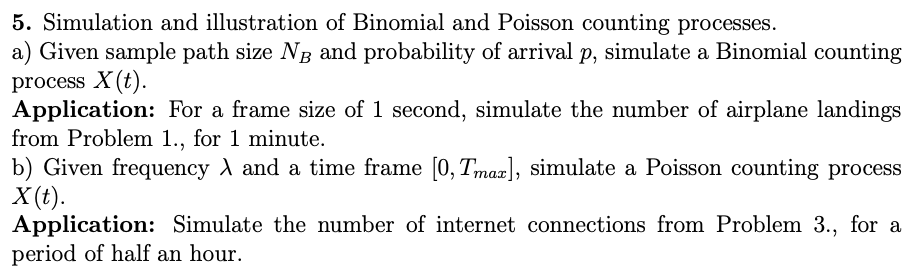

NB = 60 % simulation time frame seconds

NB =     60


p = 0.1; % probability of success (arrival)


X = zeros(1, NB); % allocate memory for X
X(1) = (rand < p); % first Bernoulli trial; X nr. of successes
for t = 2 : NB
    X(t) = X(t - 1) + (rand < p); % count the nr. of successes
end
X

X =      0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


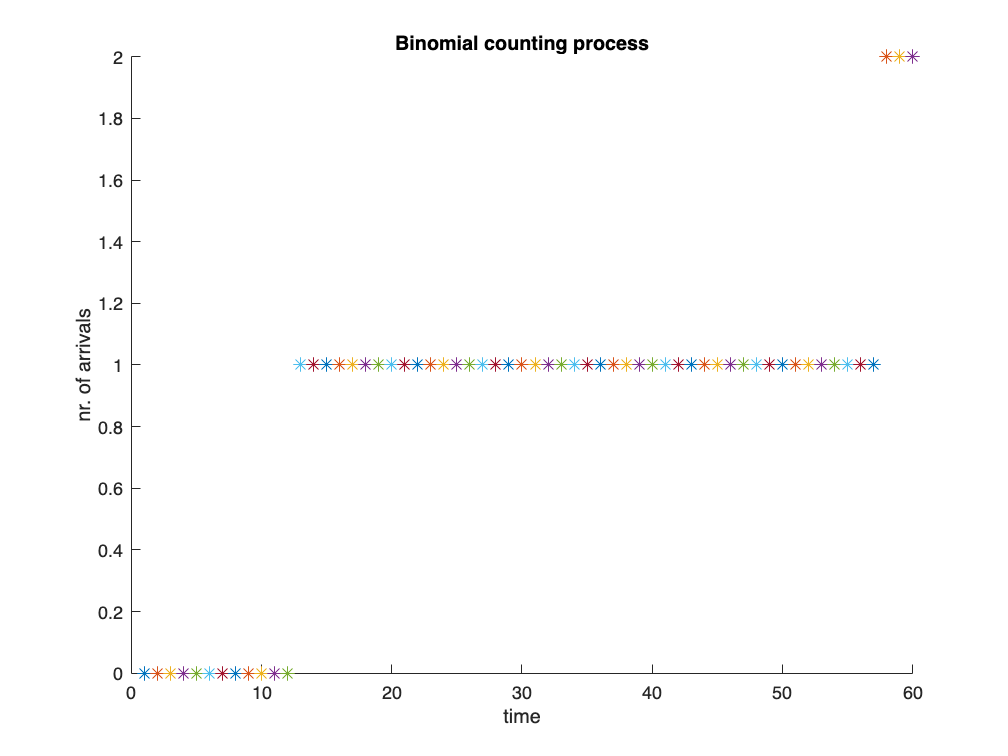


clf
axis([0 NB 0 max(X)]); % allocate the box for the entire simulated segment
hold on
title('Binomial counting process')
xlabel('time');
ylabel('nr. of arrivals')
for t = 1:NB
    plot(t, X(t), '*', 'MarkerSize', 8); hold on
    % plot each point with a '*'
end
hold off

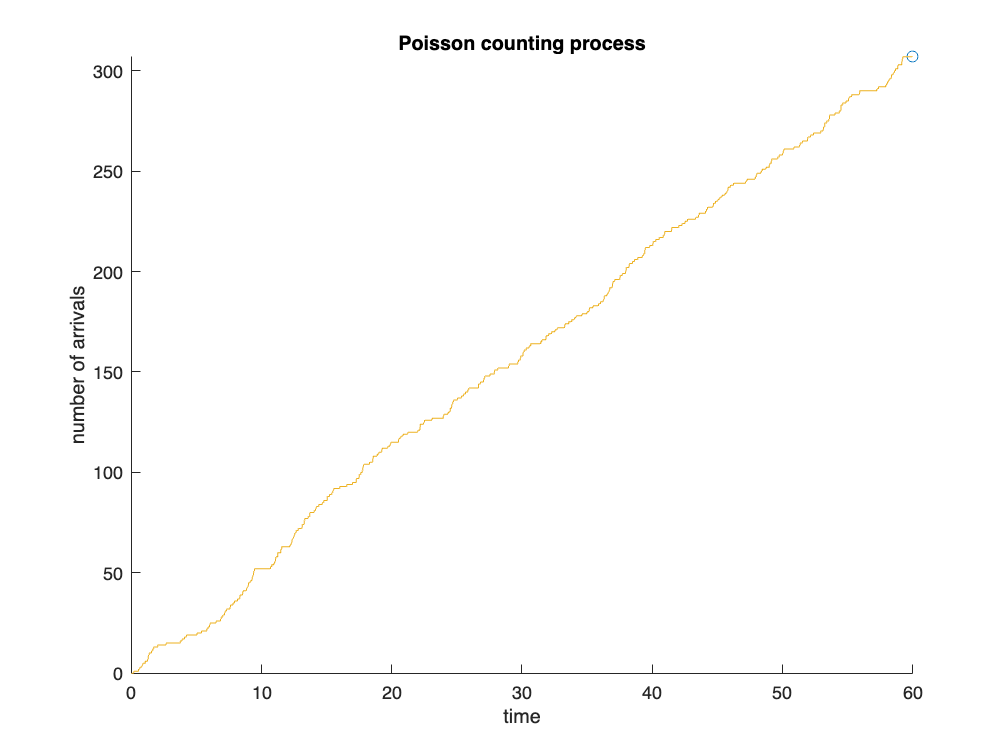

lambda = 5; % given frequency lambda
Tmax = 60; % given time frame period (in minutes)
arr_times = -1/lambda * log(rand); % array containing arrival times
                                   % each interarriv. time is Exp(lambda)
last_arrival = arr_times;
while last_arrival <= Tmax
    last_arrival = last_arrival - 1/lambda * log(rand);
    arr_times = [arr_times, last_arrival];
end

arr_times = arr_times(1 : end - 1); % nr. of arrivals during time Tmax
% last last_arrival should not be included

%%% Graph the trajectory %%%
step = 0.01; % small step size, simulate continuity
t = 0 : step: Tmax; % time variable
Nsteps = length(t);
X = zeros(1, Nsteps); % Poisson process X(t)
for s = 1 : Nsteps
    X(s) = sum(arr_times <= t(s));
end % X(s) is the number of arrivals by the time t(s)
% X

% illustration
clf
axis([0 max(t) 0 max(X)]); hold on
title('Poisson counting process')
xlabel('time'); ylabel('number of arrivals')
comet(t, X);